# Analisi Algoritmo Risolve

In questa documentazione si mostreranno i casi di test relativi all'algoritmo risolve.

# Test di accuratezza

Il  test di accuratezza da informazioni su qual'è l'errore prodotto dall'algoritmo risolve sulla soluzione calcolata. Infatti via software andiamo a risolvere un problema che è perturbato dove i dati del sistema hanno errore di round off. Non si potrà mai avere una soluzione del sistema che sia vera ma vogliamo capire quanto essa ci  si avvicini . Si utilizzerà la funzione Calcolo_Accuratezza che a partire da un problema con relativa soluzione(**parametri di input**) calcola l'errore relativo della soluzione. La funzione restituirà oltre all'errore relativo anche l'indice di condizionamento.Quest'ultimo  è strettamento legato all'errore che possiamo avere, infatti,ci da una misura di quanto l'errore di round off sui dati di input venga amplificato nell'errore di uscita. 

Si analizzeranno tre casi:

- **Matrice triangolare superiore: **utilizzo l'algoritmo back_substitution per risolvere il sistema.

- **Matrice triangolare inferiore: **utilizzo l'algoritmo di forward_substitution per risolvere il sistema.

- **Matrice piena:**Utilizzo l'algoritmo di Gauss con pivot parziale virtuale per calcolare la soluzione.

In ognuno dei 3 casi potremo avere che la matrice di input è mal condizionata o   ben condizionata,nell'ultimo caso come si osserverà dal codice si impone che la matrice sia non singolare ponendo  gli elementi della diagonale almeno pari ad 1.

%% Matrice Triangolare Superiore ben condizionata
A = triu(rand(200)) + 2*diag(ones(200,1)); 
x = ones(200,1);
b = A*x;
[indice_cond, err] = Calcolo_Accuratezza(A,x,b,'sup')

indice_cond = 386.4446

err = 1.3359e-14

%% Matrice Triangolare Superiore mal condizionata
A = triu(rand(200));
x = ones(200,1);
b = A*x;
[indice_cond,err] =Calcolo_Accuratezza (A,x,b,'sup')

indice_cond = 1.6793e+19

err = 3.9451e+12

In tal caso si sono perse tutte le cifre significative del risultato.

%% Matrice Triangolare inferiore ben condizionata
A = tril(rand(200)) + 2*diag(ones(200,1)); 
x = ones(200,1);
b = A*x;
[indice_cond, err] = Calcolo_Accuratezza(A,x,b,'inf')

indice_cond = 383.2906

err = 1.1324e-14

%% Matrice Triangolare inferiore mal condizionata
A = tril(rand(200)); 
x = ones(200,1);
b = A*x;
[indice_cond, err] = Calcolo_Accuratezza(A,x,b,'inf')

indice_cond = 2.8653e+18

err = 1.5134e+29

Per le matrici piene che prevedono l'utilizzo dell'algoritmo di Gauss con pivoting si verifica la validità del **teorema di Wilkinson**.

%%Matrice Piena
A = rand(200);
x = ones(200,1);
b = A*x;
[indice_cond, err, residuo] =Calcolo_Accuratezza (A,x,b,'full')

indice_cond = 1.4432e+04

err = 4.1985e-14

residuo = 7.1260e-16

Il residuo e l'errore in tal caso sono quasi uguali la loro differenza è circa pari all'indice di condizionamento.

%%Matrice di Hilbert:molto malcondizionata
A =hilb(10);
x = ones(10,1);
b = A*x;
[indice_cond, err, residuo] = Calcolo_Accuratezza(A,x,b,'full')

indice_cond = 1.6025e+13

err = 3.0897e-04

residuo = 6.2367e-17

Nel caso delle matrici piene Calcolo_Accuratezza restituisce anche il residuo che notiamo essere tanto più vicino all'errore relativo quanto più l'indice di condizionamento è piccolo. Infatti l'errore per tali matrici(quando ben condizionate) può essere espresso come il prodotto tra l'indice di condizionamento ed il residuo stesso.

# Valutazione Performance

Attraverso la funzione `valuta_performance `è stato valutato il tempo di esecuzione dell'algoritmo implementato. A partire da una matrice random di 200 elementi sono state effettuate tre misurazioni a seconda del tipo di matrici considerate.

- **Matrice triangolare superiore**

- **Matrice triangolare inferiore**

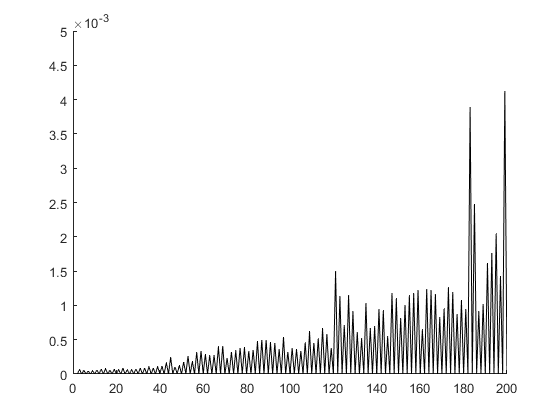

Valuta_Performance(1,200,1,'inf')

drawnow limitrate


- **Matrice piena**

Nel caso della matrice piena è stato effettuato un confronto con i tempi di esecuzione della funzione mldivide(/). Quest'ultima è la migliore implementazione esistente dell'algoritmo di Gauss. Si è scelto per maggior chiarezza di graficare l'andamento dell'indice di condizionamento,errore e residuo per le matrici generate.

## Riferimenti               

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**